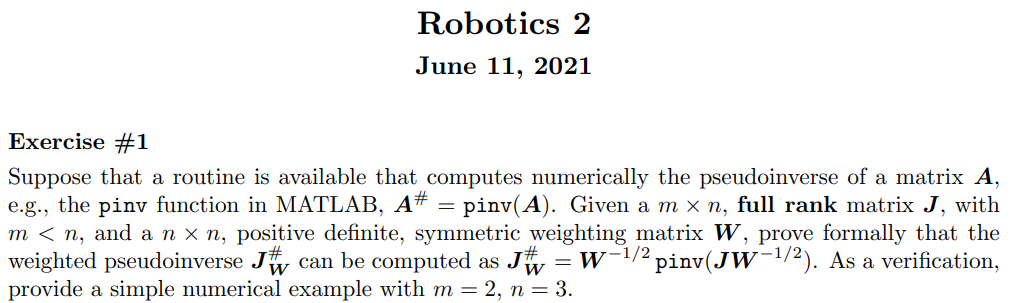

## Exercise 2

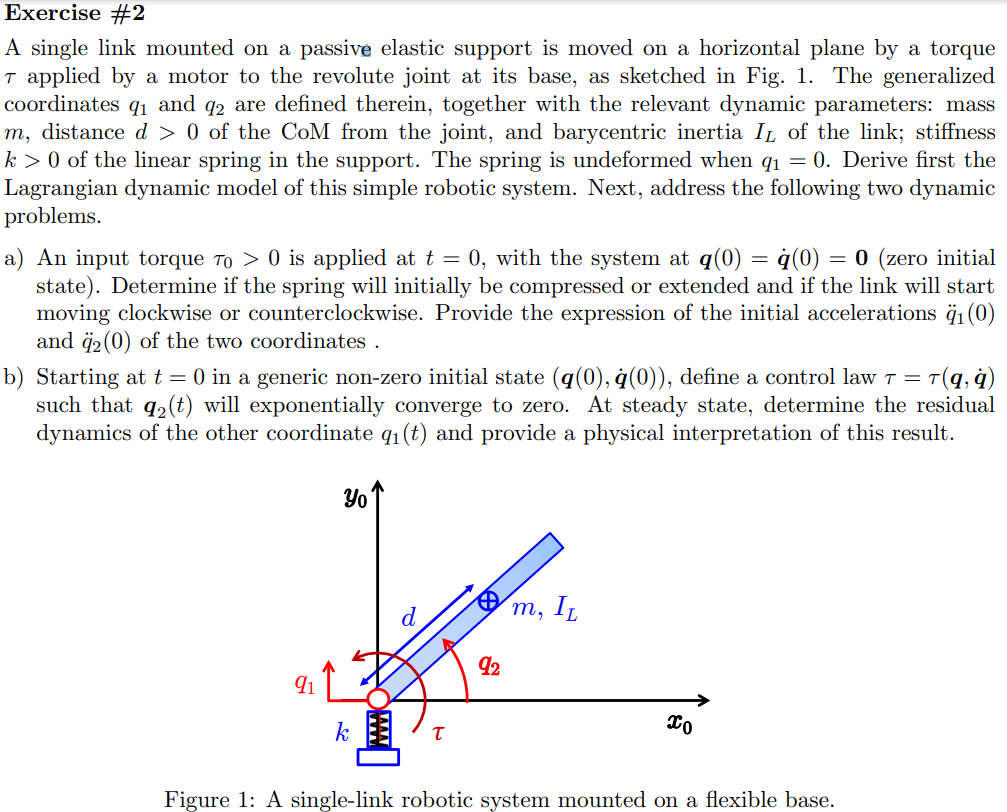

% % % % % This part is isolated from previous section
% % clear;clc
% % % %
% % % % % syms k q1(t) q2(t) q3(t)
% % sigma = [1];
% % R2Robot=['s';'x';sigma];
% % n = length(sigma);
% % t = sym('t', 'real');
% % 
% % x_r=sym('x_r','real');
% % x_r_dot=sym('x_dot_r','real');
% % x_r_ddot=sym('x_ddot_r','real');
% % 
% % x_w=sym('x_w','real');
% % x_w_dot=sym('x_dot_w','real');
% % x_w_ddot=sym('x_ddot_w','real');
% % 
% % m_r=sym('m_r','real');
% % m_w=sym('m_w','real');
% % 
% % F_r=sym('F_r','real');
% % F_w=0*sym('F_w','real');
% % 
% % 
% % b_r=sym('b_r','real');
% % b_s=sym('b_s','real');
% % b_w=sym('b_w','real');
% % 
% % k_r=0*sym('k_r','real');
% % k_s=sym('k_s','real');
% % k_w=sym('k_w','real');
% % 
% % q = sym('q_', [n 1],'real');
% % q_derivated=derivate_D(q,n,t,'q');
% % qd = q_derivated.dot;
% % qdd = q_derivated.ddot;
% % 
% % z = Gen_param(n);
% % 
% % z.sigmaD=R2Robot;
% % z.q=q;
% % z.q_dot=qd;
% % z.q_ddot=qdd;
% % 
% % % z.q=[x_r,x_w]';
% % % z.q_dot=[x_r_dot,x_w_dot]';
% % % z.q_ddot=[x_r_ddot,x_w_ddot]';
% % z.k=[k_r,k_s,k_w]' ;
% % z.b=0*[b_r,b_s,b_w]' ;
% % z.m_spring=[m_r,m_w]' ;
% % z.F=[F_r,F_w]' ;
% % 

% % [spring_models,F_springs_,z]=Spring_model(z);

% % % F_spring_(1,1)=spring_models(1).F_;
% % % F_spring_(2,1)=spring_models(2).F_;
% % % F_spring_=collect(expand(F_spring_),[z.k;z.b])
% % 
% % F_spring_=collect(expand(F_springs_),[z.k;z.b])

% % expand(sum(F_spring_))

% 
% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['pr';'yx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% z.opt_expr={[m(1)],[0]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % %             0       , z.l(2)  , 0   , q(2);]

% 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Ti(1)
% Pc
% M
% 

## Potential energy definition

% %special potential energy
% k=sym('k','real')
% f_u=[(k*z.q(1).^2)/2,0]'

% isMotor=false
% 
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)
% [grad_f,PE, U,grad_f_short,PE_short] = getGradient(f_u,z.q)%,gradient computation

% U{:}

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)
% 

% C{1}
% cac
% S

% 

## Final model

% tau_2=sym('tau_2','real')
% tau=[0,tau_2]'
% dyn_model=M*z.q_ddot+cac+grad_f==tau

% M_0=subs(M,[q;q_dot],[0,0,0,0]')
% M_inv_0=expand(pinv(M_0))
% q_0_ddot=simplify(M_inv_0*tau)

% simplify(expand(pinv(M)))

% q_ddot_sym=simplify(expand(pinv(M))*((tau-cac-grad_f)))

% 
% % dyn_model(1)==tau_1
% q1_ddot_=expand(rhs(isolate(dyn_model(1),z.q_ddot(1))))
% 
% eq2=expand(subs(dyn_model(2),z.q_ddot(1),q1_ddot_))
% tau_=collect((expand(rhs(isolate(eq2,tau_1)))),z.q_ddot)

## Exercise 3

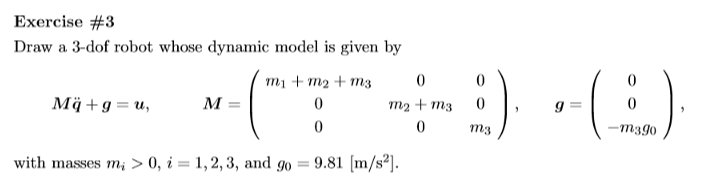

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,1,1];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['ppp';'xyz';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2; %apy attention to this
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % % %             0       , z.l(2)  , 0   , q(2);]

% % % % 
% % % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Ti(1)
% T
% Pc
% M


## Exercise 4

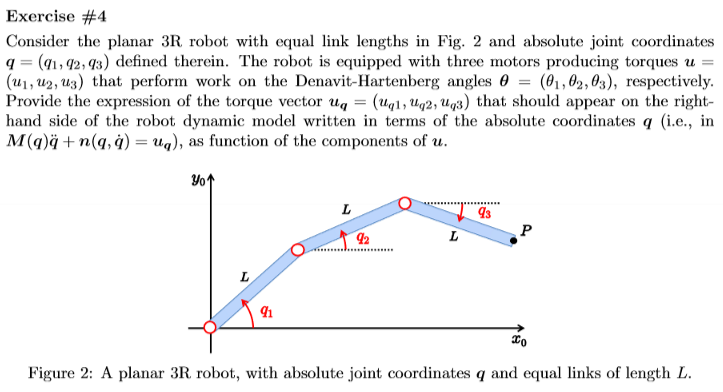

% 
% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l_0 = sym('l','real');
% l = ones([n 1])*l_0;%sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2; %apy attention to this
% z.xyonly=true
% z.global_q_reference=true %global referenes
% z.q_global=z.q;
% z.q_dot_global=z.q_dot;
% z.q_ddot_global=z.q_ddot;
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % % %             0       , z.l(2)  , 0   , q(2);]

% % % % 
% % % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Ti(1)
% T
% Pc
% M

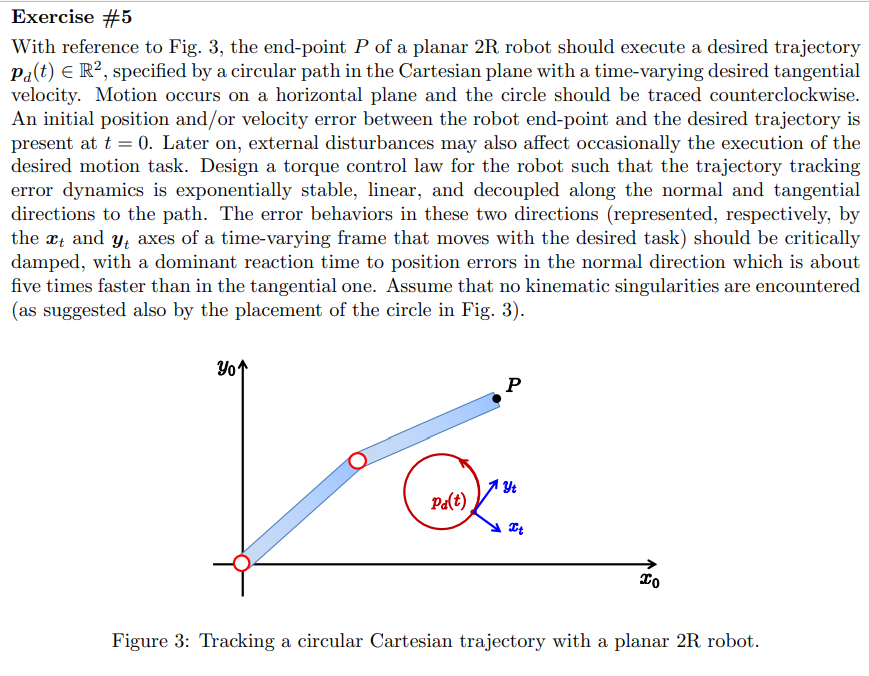



% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rr';'xx';sigmaD]

R2Robot = 3×2 char array
    'rr'
    'xx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
% l(1)=0 %don't do this because dc1 is going to dissaperar
% z.opt_expr={[l(1)],[0]};%use this instead
z.opt_expr={[m(1)],[0]};%use this instead
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {m1  [0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));

% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {m1  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {m1  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$f = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$V = \left(\begin{array}{c} -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) \end{array}\right)$$

$$J\_ps = \left(\begin{array}{cc} \frac{\cos\left(q_{1}+q_{2}\right)}{l_{1}\,\sin\left(q_{2}\right)} & \frac{\sin\left(q_{1}+q_{2}\right)}{l_{1}\,\sin\left(q_{2}\right)}\\ -\frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)} & -\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)}{l_{1}\,l_{2}\,\sin\left(q_{2}\right)} \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [2×2 sym]
              Pc: [3×2 sym]
              vc: [3×2 sym]
     f_derivated: [1×1 struct]
           f_dot: [2×1 sym]
          f_ddot: [2×1 sym]
          f_tdot: [2×1 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×2 sym]
               w: [3×2 sym]
               T: (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (I1*q_dot_1^2)/2
              Ti: [(I1*q_dot_1^2)/2    (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2]
               M: [2×2 sym]


PC_EEShort = struct with fields:
              f: [2×1 sym]
              J: [2×2 sym]
    J_dot_short: [2×2 sym]
              V: [2×1 sym]
             Pc: [3×2 sym]
        Pc_ddot: []
        PTotali: [3×2 sym]


VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (I1*q_dot_1^2)/2
    Ti: [(I1*q_dot_1^2)/2    (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2]
     M: [2×2 sym]


% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

f

$$f = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

% Ti(1)
% Pc
% M

z_path_params.func_name="circular";
z_path_params.replacevars=true;
z_path_params.dir=1;
z_path_params.C_=[7,0]';
z_path_params.R_=3;
z_path_params.v_=1;
xyonly_=true

xyonly_ = logical
   1


z_path = common_trajectory_func(z_path_params,xyonly_);

z_path = struct with fields:
      func_name: "circular"
    replacevars: 1
            dir: 1
             C_: [2×1 double]
             R_: 3
             v_: 1
              C: [2×1 sym]


z_path.rd_theta

$$ans = \left(\begin{array}{c} C_{1}+R\,\cos\left(\theta \right)\\ C_{2}+R\,\sin\left(\theta \right) \end{array}\right)$$

z_path.rd_t

$$ans = \left(\begin{array}{c} C_{1}+R\,\cos\left(\frac{t\,v}{R}\right)\\ C_{2}+R\,\sin\left(\frac{t\,v}{R}\right) \end{array}\right)$$

z_path.rd_t_dot

$$ans = \left(\begin{array}{c} -v\,\sin\left(\frac{t\,v}{R}\right)\\ v\,\cos\left(\frac{t\,v}{R}\right) \end{array}\right)$$

z_path.rd_t_ddot

$$ans = \left(\begin{array}{c} -\frac{v^{2}\,\cos\left(\frac{t\,v}{R}\right)}{R}\\ -\frac{v^{2}\,\sin\left(\frac{t\,v}{R}\right)}{R} \end{array}\right)$$

if(z_path_params.replacevars)
    z_path.rd_theta_
    z_path.rd_theta_dot_
    z_path.rd_theta_ddot_
    
    z_path.rd_t_
    z_path.rd_t_dot_
    z_path.rd_t_ddot_
    
end

$$ans = \left(\begin{array}{c} 3\,\cos\left(\theta \right)+7\\ 3\,\sin\left(\theta \right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\sin\left(\theta \right)\\ \cos\left(\theta \right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\frac{\cos\left(\theta \right)}{3}\\ -\frac{\sin\left(\theta \right)}{3} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 3\,\cos\left(\frac{t}{3}\right)+7\\ 3\,\sin\left(\frac{t}{3}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\sin\left(\frac{t}{3}\right)\\ \cos\left(\frac{t}{3}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} -\frac{\cos\left(\frac{t}{3}\right)}{3}\\ -\frac{\sin\left(\frac{t}{3}\right)}{3} \end{array}\right)$$

beta=sym('beta','real');
[Re, R_set] = getRotMatProduct('Z',0,[ beta])

$$Re = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & 0\\ \sin\left(\beta \right) & \cos\left(\beta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_set = 1×1 cell array
    {3×3 sym}


## Potential energy definition

% %special potential energy
% k=sym('k','real')
% f_u=[(k*z.q(1).^2)/2,0]'

% isMotor=false
% 
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)
% [grad_f,PE, U,grad_f_short,PE_short] = getGradient(f_u,z.q)%,gradient computation

% U{:}

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)
% 

% C{1}
% cac
% S

% 

## Final model

% tau_2=sym('tau_2','real')
% tau=[0,tau_2]'
% dyn_model=M*z.q_ddot+cac+grad_f==tau

% M_0=subs(M,[q;q_dot],[0,0,0,0]')
% M_inv_0=expand(pinv(M_0))
% q_0_ddot=simplify(M_inv_0*tau)

% simplify(expand(pinv(M)))

% q_ddot_sym=simplify(expand(pinv(M))*((tau-cac-grad_f)))

% 
% % dyn_model(1)==tau_1
% q1_ddot_=expand(rhs(isolate(dyn_model(1),z.q_ddot(1))))
% 
% eq2=expand(subs(dyn_model(2),z.q_ddot(1),q1_ddot_))
% tau_=collect((expand(rhs(isolate(eq2,tau_1)))),z.q_ddot)